# Linear Regression

## 1 `L`inear regression with one variable 

clear; 
close all;
clc;

% load data
data = load('ex1data1.txt');
X = data(:, 1); 
y = data(:, 2);
m = length(y); % number of training examples

X = [ones(m, 1), X]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters

% Gradient descent
iterations = 1000;
alpha = 0.01;
[theta, J_history, theta_history] = gradientDescent(X, y, theta, alpha, iterations);

disp(array2table(theta));

     theta 
    _______

    -3.2414
     1.1273



% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
predict2 = [1, 7] * theta;
info0 = table([predict1*10000; predict2*10000],'RowNames', {'population = 35,000','population = 70,000'},'VariableNames',"Predict profit")

info0 = 2×1 table
                           Predict profit
                           ______________

    population = 35,000        7041.3    
    population = 70,000         46497    


### Visualizing data and linear regression

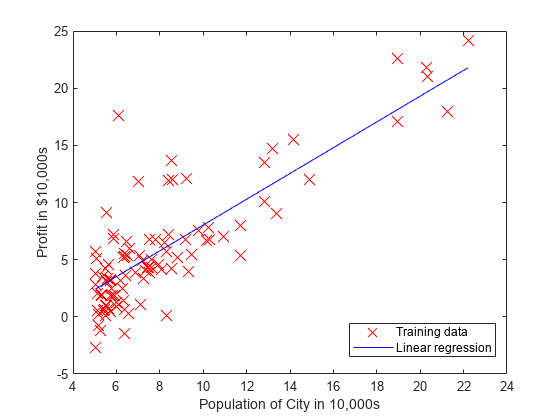

figure
plot(X(:,2), y, 'rx', 'MarkerSize', 10);      % Plot the data
ylabel('Profit in $10,000s');            % Set the y−axis label
xlabel('Population of City in 10,000s'); % Set the x−axis label
hold on;
plot(X(:,2), X*theta, 'b-')
legend('Training data', 'Linear regression')
hold off;
legend("Position", [0.63,0.15,0.25,0.08])

### Visualizing J (theta_0, theta_1)

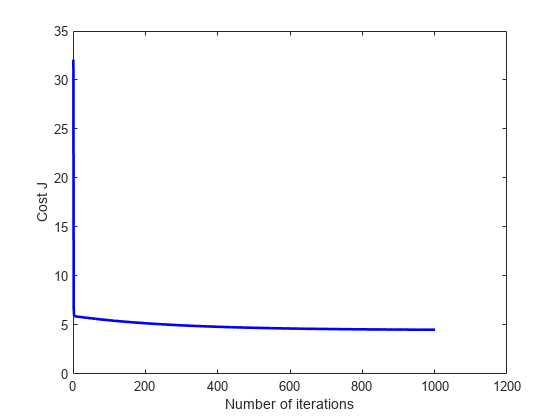

% Plot the convergence graph
figure;
plot(1:numel(J_history), J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

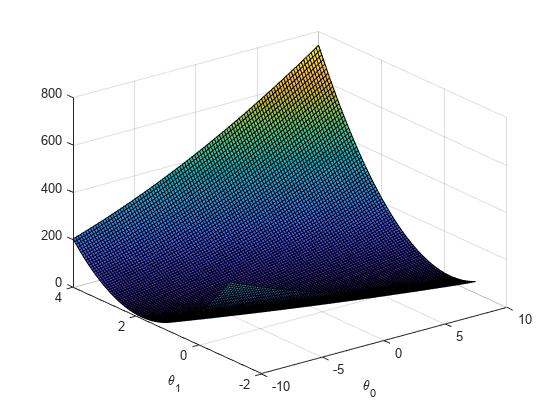

% 遍历范围计算J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);
J_vals = zeros(length(theta0_vals), length(theta1_vals));
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];
	  J_vals(i,j) = computeCost(X, y, t);
    end
end
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); 
ylabel('\theta_1');

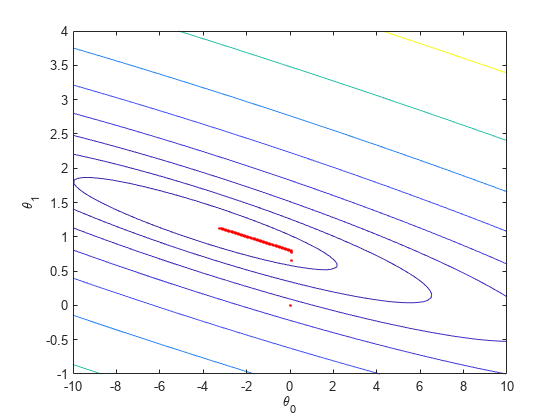

% Contour plot
figure;
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); 
ylabel('\theta_1');
hold on;
for idx = 1:size(theta_history,3)
    theta = theta_history(:,:,idx);
    plot(theta(1), theta(2), 'rx', 'MarkerSize', 1, 'LineWidth', 2);
end
hold off;

## 2 `L`inear regression with multiple variable 

clear; 

data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

### Gradient descent Method

% Scale features
[X, mu, sigma] = featureNormalize(X);

% Add intercept term to X
X = [ones(m, 1) X];

% Gradient descent
alpha = 0.01;
num_iters = 400;
theta = zeros(3, 1);
[theta, J_history, ~] = gradientDescent(X, y, theta, alpha, num_iters);

% Estimate the price of a 1650 sq-ft, 3 br house
% Recall that the first column of X is all-ones. Thus, it does
% not need to be normalized.
input_X = ([1650, 3]-mu)./sigma;
price_pridict_by_gradient_descent = [1,input_X]*theta;

disp(array2table(theta));

      theta   
    __________

     3.343e+05
    1.0009e+05
        3673.5



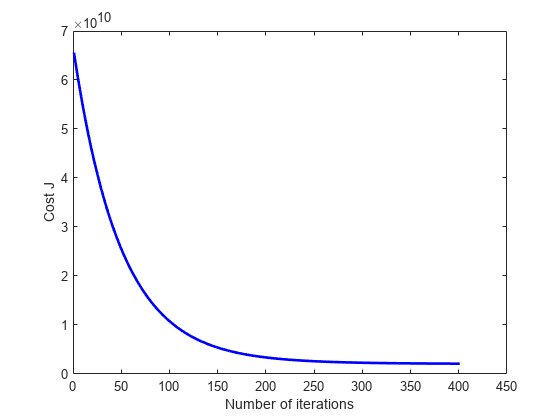

% Plot the convergence graph
figure;
plot(1:numel(J_history), J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

### Normal Equations Method

使用本方法不需要Scale features。

% Normal Equations
X = data(:, 1:2);
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Estimate the price of a 1650 sq-ft, 3 br house
price_pridict_by_normal_equation = [1,1650,3]*theta;

disp(array2table(theta));

    theta 
    ______

     89598
    139.21
     -8738



### 两种方法比较

info1 = table([price_pridict_by_gradient_descent; price_pridict_by_normal_equation],'RowNames', {'Gradient descent','Normal equation'},'VariableNames',"Predict price")

info1 = 2×1 table
                        Predict price
                        _____________

    Gradient descent     2.8931e+05  
    Normal equation      2.9308e+05  


## Local Function

**Cost function**

**Batch gradient descent**

**Normal Equations**

function J = computeCost(X, y, theta)
%COMPUTECOST Compute cost for linear regression
%   J = COMPUTECOST(X, y, theta) computes the cost of using theta as the
%   parameter for linear regression to fit the data points in X and y

    m = length(y); 
    % J = sum((X*theta -y).^2)/(2*m);
    J = (X*theta - y)'*(X*theta - y)/(2*m);

end

function [theta, J_history, theta_history] = gradientDescent(X, y, theta, alpha, num_iters)
%GRADIENTDESCENT Performs gradient descent to learn theta
%   theta = GRADIENTDESCENT(X, y, theta, alpha, num_iters) updates theta by 
%   taking num_iters gradient steps with learning rate alpha

    m = length(y);

    J_history = zeros(num_iters+1, 1);
    theta_history = repmat(zeros(size(theta)),[1,1,num_iters+1]);
    J_history(1) = computeCost(X, y, theta);
    theta_history(:,:,1) = theta;

    for iter = 1:num_iters
        delta_theta = X'*(X*theta - y)/m;
        theta = theta - alpha*delta_theta;
        J_history(iter+1) = computeCost(X, y, theta);
        theta_history(:,:,iter+1) = theta;
    end

end

function [X_norm, mu, sigma] = featureNormalize(X)
%FEATURENORMALIZE Normalizes the features in X 
%   FEATURENORMALIZE(X) returns a normalized version of X where
%   the mean value of each feature is 0 and the standard deviation
%   is 1. This is often a good preprocessing step to do when
%   working with learning algorithms.

    m = length(X);
    mu = mean(X);
    sigma = std(X);
    X_norm = (X - repmat(mu,m,1))./sigma;

end

function [theta] = normalEqn(X, y)
%NORMALEQN Computes the closed-form solution to linear regression 
%   NORMALEQN(X,y) computes the closed-form solution to linear 
%   regression using the normal equations.

    theta = (X'*X)^-1*X'*y;

end